# **1a. Nonlinear ****Equation Solving**** (**`fzero` **and** `fsolve`**)**

clear;
disp('********************************************')

********************************************


disp('Example 1:')

Example 1:


disp('********************************************')

********************************************


**Example 1a:** Use `fzero` to solve $x^2=2$ for $x$.

f01=@(x) x^2-2;
x=fzero(f01, 1)

x = 1.4142

[x, fval, exitflag, output]=fzero(f01, 1)

x = 1.4142

fval = 4.4409e-16

exitflag = 1

output =     intervaliterations: 9
            iterations: 6
             funcCount: 25
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.547452, 1.45255]'

Alternatively, we can use

clear;
clc;
x=fzero(@f02, 1)

x = 1.4142

[x, fval, exitflag, output]=fzero(@f02, 1)

x = 1.4142

fval = 4.4409e-16

exitflag = 1

output =     intervaliterations: 9
            iterations: 6
             funcCount: 25
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [0.547452, 1.45255]'

**Example 1b:** Use `fsolve` to solve $x^2=2$ for $x$.

f01=@(x) x^2-2;
x=fsolve(f01, 1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x = 1.4142

[x, fval, exitflag, output]=fsolve(f01, 1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x = 1.4142

fval = 4.5040e-12

exitflag = 1

output =        iterations: 4
        funcCount: 10
        algorithm: 'trust-region-dogleg'
    firstorderopt: 1.2739e-11
          message: 'Equation solved.…'

Alternatively, we can use

clear;
clc;
x=fsolve(@f02, 1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x = 1.4142

[x, fval, exitflag, output]=fsolve(@f02, 1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x = 1.4142

fval = 4.5040e-12

exitflag = 1

output =        iterations: 4
        funcCount: 10
        algorithm: 'trust-region-dogleg'
    firstorderopt: 1.2739e-11
          message: 'Equation solved.…'

**How to obtain the negative root?**

% Method 1a
x=fzero(@f02, -1)

x = -1.4142

% Method 1b
x=fsolve(@f02, -1)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x = -1.4142

% Method 2
x=fzero(@f02, [-10, 0])

x = -1.4142

clear;
disp('********************************************')
disp('Example 2:')

x = -1.1447

disp('********************************************')

**Example 2:** Given $f(x,a,b)=ax^3+b$, solve $f(x,2,3)=0$.

a=2;
b=3;

ans = 9

x=fzero(@(x) fxab(x,a,b), 1)

**Functions tha****t return a function (1)**

f=flist(1,4);
f(3)

fun=@(a,b) @(x) a*x+b;

ans = 11

f=fun(2,3);
f(4)

**Functions t****hat return a function (2)**

f=flist2();
[f3,f5]=f{:};

ans =     15    25

[f3(5), f5(5)]

i=3;
f=@(x) i*x;
i=5;
disp(f(5));

    15


i=7;
disp(f(5));

    15


clear;
disp('********************************************')

********************************************


disp('Example 3:')

Example 3:


disp('********************************************')

********************************************


**Example 3:** Given $S=490$, $K=470$, $r=0.033$, $q=0$, $T=0.08$ and $c=24.5941$, use function `fzero` and `BS_EuroCall` to solve the Black-Scholes equation for the implied volatility ($\sigma$).

% Type your answer below.


clear;

sigma_imp = 0.2000

disp('********************************************')
disp('Example 4:')
disp('********************************************')

********************************************


**Example 4: **Find the implied volatility for each row of a table.

1. Use `readtable` to get the data from file `dataset01.csv`. Name the data imported as `data`.

data=readtable('dataset01.csv');

Example 3:


disp(data)

********************************************


2. Compute implied volatility for each row, and put the result in a new column with the column name `ImpVol`.

3. Write `data` to a CSV file `ou``tput.csv`.

writetable(data,'output.csv');

clear;

     S       K        r         q       sigma       T         c   
    ____    ____    ______    ______    _____    _______    ______
    1403    1350    0.0534    0.0118     0.26    0.10278    80.828
    1403    1375    0.0534    0.0118    0.267    0.10278    66.084
    1403    1400    0.0534    0.0118    0.231    0.10278    45.894
    1403    1425    0.0534    0.0118    0.213    0.10278    30.955
    1403    1450    0.0534    0.0118    0.198    0.10278    19.224


disp('********************************************')
disp('Example 4:')

data =      S       K        r         q       sigma       T         c       ImpVol
    ____    ____    ______    ______    _____    _______    ______    ______
    1403    1350    0.0534    0.0118     0.26    0.10278    80.828     0.26 
    1403    1375    0.0534    0.0118    0.267    0.10278    66.084    0.267 
    1403    1400    0.0534    0.0118    0.231    0.10278    45.894    0.231 
    1403    1425    0.0534    0.0118    0.213    0.10278    30.955    0.213 
    1403    1450    0.0534    0.0118    0.198    0.10278    19.224    0.198 

disp('********************************************')

# **1b. System of Nonlinear ****Equations Solving**** (**`fsolve`**)**

**Example 5:** Solve the following system of nonlinear equations for $x_0$ and $x_1$.


$$\left\{ 
\begin{array}{l}
x_0 \cos (x_1)=4 \\
x_0 x_1 -x_1 =5
\end{array}
\right.$$


x=fsolve(@f03, [1,1])

# **2a. Constrained Optimization (**`fmincon`**)**

**Example 6: **Optimization with constraints

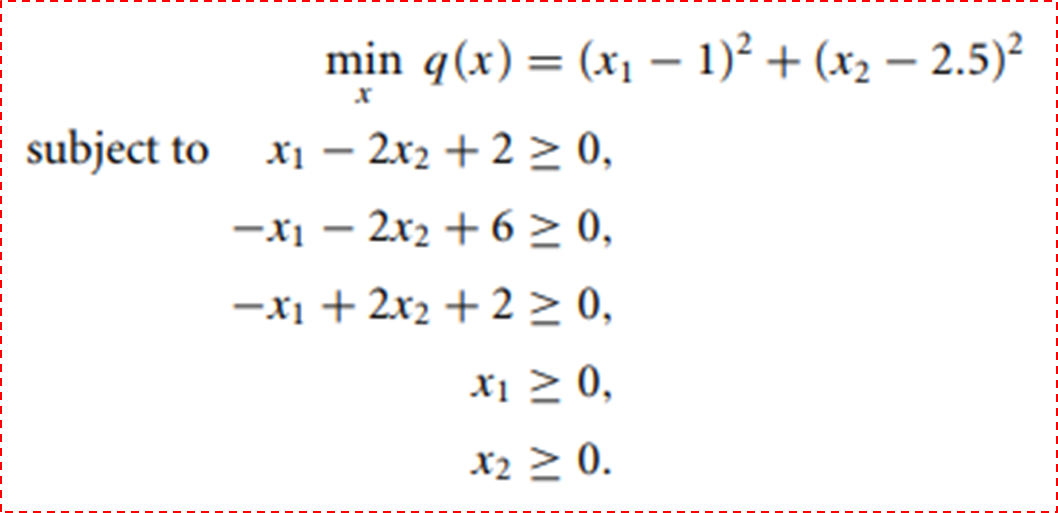

fun=@(x) (x(1)-1)^2+(x(2)-2.5)^2;
A=[-1 2;1 2;1 -2];

********************************************


b=[2;6;2];

Example 4:


Aeq=[];

********************************************


beq=[];
lb=[0 0];
ub=[];
x0=[0 0];
x= fmincon(fun,x0,A,b,Aeq,beq,lb,ub)

# **2b. Quadratic Programming (**`quadprog`**)**

**Example 7: **Quadratic Programming with linear constraints

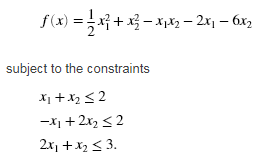

H = [1 -1; -1 2]; 


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x =     6.5041    0.9084

f = [-2; -6];
A = [1 1; -1 2; 2 1];
b = [2; 2; 3];
x = quadprog(H,f,A,b)

**Example 8: **Minimum-Variance Portfolio by `quadprog`

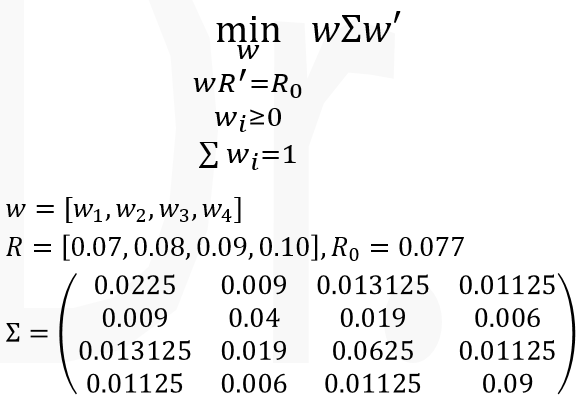

V=;
f=;
A=;
b=;
Aeq=;
beq=;
lb=;
ub=;
w=quadprog(, f, A, b, Aeq, beq, lb, ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

x =     1.4000    1.7000

# **3. Approximate Derivatives with **`diff`

h=0.001;
X=-pi:h:pi;
f=sin(X);
Y=diff(f)/h;
Z=diff(Y)/h;


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

x =     0.6667
    1.3333

plot(X(:,1:length(Y)),Y,'r',X,f,'b',X(:,1:length(Z)),Z,'k')

# **4. Integration (**`integral`**, **`integral2`**, ..., etc.)**

**Example ?: Co****mpute **$\int_0^4 x^2 dx$**.**

x2=@(x) x.^2;
p=integral(x2, 0, 4)

**Example ?: Comp****ute **$\int_0^\infty e^{-x} dx$**.**

f=@(x) exp(-x);
p=integral(f, 0, inf)

**Example ?: Compute **$\int_0^2 \int_0^1 xy^2 dydx$**.**

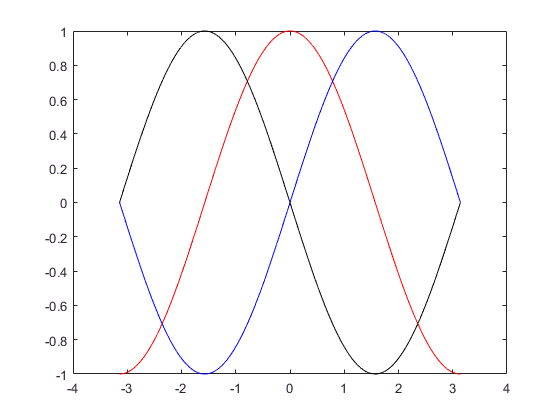

p = 21.3333

p = 1

p = 0.6667

f=@(x,y) x.*(y.^2);
p=integral2(f, 0, 2, 0, 1)